# 第 2 章  符号计算

## 2.1 引导

- **符号计算：**解算数学表达式、方程**不是**在离散化的**数值点**上进行**而是**凭借一系列恒等式，数学定理，通过推理和演绎获得**解析**结果。符号计算建立在**数值完全准确表达**和**推演严格解析**的基础之上， 所得结果**完全准确**。

- 符号运算与数值运算的主要区别：

            数值型运算受到计算机有效位数的限制，每次运算都会有截断误差,重复多次运算产生很大的累积误差

            符号运算不需要进行数值运算，不会出现截断误差，因此是完全准确的。

            符号运算可以得出完全的封闭解或任意精度的数值解。

            相对于MATLAB的数值计算“引擎”和“函数库”而言，

**            符号计算的****“引擎”和“函数库”是独立的**。

            符号对象必须先定义后使用

- MATLAB符号计算的基本要义：

            基本符号对象：符号数字，符号变量，符号抽象函数，符号抽象数组

            MATLAB的符号表达式和函符号函数的构成：

            由基本符号对象、符号运算符、符号工具包预定义函数构成

            若符号运算解析受阻得不出解析结果或解算耗时太长

            可实施由符号计算引擎提供的有限精度计算。

- 任何基本**符号对象**（数字、参数、变量、表达式、函数）

            都必须借助专门的符号函数指令sym、 syms或symfun定义。

- **任何包含符号对象的表达式或方程，将继承符号对象的属性**。

            即任何包含符号对象的表达式、方程也一定是符号对象

- **符号运算的工作机理**

            MATLAB的符号计算是由MuPAD引擎在其专有的内存工作空间中执行只是把计算结果送回到MANTLAB的内存工作空间

            当用sym或syms定义符号变量时，就启动以下过程：

            ① 启动MuPAD引擎，开启一个专供MuPAD使用的内存空间

            ② 被定义**变量保存至****Matlab****内存空间**

            ③ 对变量的**限定性假设保存在****MuPAD****内存空间中**，

                并对以后的MuPAD工作方式进行约束

                如不带任何约束则默认工作在**复数域**；

                若带有约束integer、positive、rational、real则工作在相应的数域当中。

## 2.2 基本符号对象的创建

## 2.2.1   **符号数的创建**

## **1.** **非超长符号实数的创建**

**        sym(HandNum)            **直接由双精准**数值类的数**创建**符号数字**

**        sym(HandNum****,****Flag)**

**        sc=sym(HandNum)      **直接由双精准**数值类的数**创建**符号常数**sc

**〖说明〗**

- HandNum必须是非超长数

                即有效数字位数不超过15位，否则会引起圆整误差

- HandNum必须是单个实数

                该单个实数只能是有理数、十进制小数或浮点数的科学计数法形式

                    -35，137/273793，327.8734，1.9734e-33

- 返回值是不含误差准确表达HandNum的理论数值或理论数值的符号常数

                Flag是浮点数字转换后的表达格式：

**                '**r**'  **有理分数表达符号数字（默认）；

**                '**d**'** “十进制浮点”近似表达符号数字；

**                '**e**'**  带估计误差的“广义有理表达”符号数字;

**                '**f**'**“两个二进制数”近似表达符号数字±[2e+N×2(-52+e)]， N和e为整数

- 英文字母i、j既是数值计算环境也是符号计算环境下的虚数单元

## **2. 超长符号实数的创建**

    创建有效位数大于15位的准确符号数

**        sym('HandNum')             ****由数字字符串创建符号数**

**        sc=sym('HandNum')       ****由数字字符串创建符号常数****sc**

〖说明〗

- **Hand**Num必须处于（英文状态下的）**' '** 内，构成字符串（附录A）

- **Hand**Num可以是任意长位数的单个实数（除标准书写的有理数外）

            只能用有理数、预定义常数、十进制小数、科学计数的浮点数表示

            如321/1200，10/3，235，pi

- 也可定义非超长数。只有整数、有理数、预定义常数可保持常数不变

- 返回值是不含误差的HandNum理论数值或理论数值的符号常数变量

- 千万不能运行sym(**'i'**)或sym(**'j'**)，会引起复数表达的混乱

【例2.1-1】

（1）直接输入数字创建非超长符号实数

a1=sym(-12345678901234)	 %15位整数

$$a1 = -12345678901234$$

a2=sym(0.12345)             %少于15位的小数

$$a2 = \frac{2469}{20000}$$

a3=sym(1.627e-3)	         %少于15位的科学计数小数

$$a3 = \frac{468950821998835}{288230376151711744}$$

a4=sym(1234567/7654321)	 %少于15位的科学计数小数

$$a4 = \frac{2905546020954131}{18014398509481984}$$

（2）创建超准确的超长符号实数

b1=sym('123456789012345678901')	  %【20位符号整数''】

$$b1 = 123456789012345678901$$

b2=sym('1.23456789012345678901')    %20位符号小数

$$b2 = 1.23456789012345678901$$

b3=sym('1234567890123456789/987654321098765432198')  

$$b3 = \frac{1234567890123456789}{987654321098765432198}$$

（3）直接超长数字输入不能创建希望的准确符号数

c1=sym(123456789012345678901)	  %20位符号整数

$$c1 = 123456789012345683968$$

c2=sym(1.23456789012345678901)    %20位符号小数

$$c2 = \frac{5559999489923579}{4503599627370496}$$

c3=sym(1234567890123456789/987654321098765432198)

$$c3 = \frac{5764607470504249}{4611686018427387904}$$

## **3. 符号复数的创建**

- 创建复数，实、虚部中均不得出现运算符。

                无论创建实虚部形式还是复指数形式，**至少要出现一次****sym****指令**

- 实部+虚部的符号复数：实虚部不存在任何关联运算，可作为一个整体

                sym(1.65+3.47i)是合理的，sym((1.65/2)+(3.47+2.55)i)是不合理的

- 复指数形式的符号复数：MATLAB总是将其进行运算转换成实虚部,并以实部、虚部的形式存储。创建时一定要保证符号数字是准确的

- 创建超长实部+虚部符号复数时，实、虚部分别采用数字字符串创建法	

【例2.1-2】

（1）实虚部形式

clear
a0=sym(1.65)+sym(3.76)*sym(i)   %严谨格式

$$a0 = \frac{33}{20}+\frac{94}{25}\,\mathrm{i}$$

a1=sym(1.65)+sym(3.76i)         

$$a1 = \frac{33}{20}+\frac{94}{25}\,\mathrm{i}$$

a2=sym(1.65)+ i*sym(3.76)	   

$$a2 = \frac{33}{20}+\frac{94}{25}\,\mathrm{i}$$

a3=sym(1.65)+ 3.76i

$$a3 = \frac{33}{20}+\frac{94}{25}\,\mathrm{i}$$

a4=1.65+sym(3.76i)

$$a4 = \frac{33}{20}+\frac{94}{25}\,\mathrm{i}$$

a5=sym(1.65+3.76i)

$$a5 = \frac{33}{20}+\frac{94}{25}\,\mathrm{i}$$

isAlways(a0==a5)

ans = logical
   1


（2）复指数形式

b0=sym(2)*exp(sym(i)*sym(3)*sym(pi)/sym(4)) %严谨格式

$$b0 = \sqrt{2}\,\left(-1+\mathrm{i}\right)$$

b1=sym(2)*exp(i*pi*sym(3/4))

$$b1 = \sqrt{2}\,\left(-1+\mathrm{i}\right)$$

b2=sym(2)*exp(i*sym(pi)*3/4)

$$b2 = \sqrt{2}\,\left(-1+\mathrm{i}\right)$$

b3=2*exp(i*sym(pi)*3/4)

$$b3 = \sqrt{2}\,\left(-1+\mathrm{i}\right)$$

b4=sym(2)*exp(i*pi*3/4)

$$b4 = \sqrt{2}\,\left(-1+\mathrm{i}\right)$$

c1=3.65*exp(sym(i)*3*sin(0.5)/4)      % sin(0.5)参与了计算

$$c1 = \frac{73\,{\mathrm{e}}^{\frac{1619355507757341}{4503599627370496}\,\mathrm{i}}}{20}$$

c2=sin(3.65)*exp(sym(i)*3/sym(4))          % sin(3.65)参与了计算

$$c2 = -\frac{4384584338989481\,{\mathrm{e}}^{\frac{3}{4}\,\mathrm{i}}}{9007199254740992}$$

d0=sym('1.23456789012345678')+sym('9.87654321098765432')*i

$$d0 = 1.23456789012345678+9.87654321098765432\,\mathrm{i}$$

d1=1.23456789012345678+sym('9.87654321098765432')*i

$$d1 = 1.2345678901234566904321354741114+9.87654321098765432\,\mathrm{i}$$

d1=sym('1.23456789012345678')+9.87654321098765432*i

$$d1 = 1.23456789012345678+9.8765432109876538646631161100231\,\mathrm{i}$$

## **2.2.2** **符号变量的创建**

**1.** 基本符号变量的创建

经典教科书里，表达式e-axsinbx中的a,b称为参数，x称为变量。

在MATLAB的符号计算中，a、b、x统称为**基本符号变量**

其中x总被默认为**自由（待解）符号变量**，

其它基本符号变量被作为**符号参数**处理。

定义**基本符号变量**的指令格式：

**pr=sym('pr') **                      定义单个**复数域**符号变量pr

**syms pr1 pr2****…**** prN **          定义多个**复数域**符号变量para1…paraN 

〖说明〗

- sym只对**单变量**作用，可创建符号数字/符号常数/符号矩阵

                syms可定义多个符号变量，各变量名之间必须用空格隔开

                syms不能用于对数值、符号常数的定义。

- 符号变量的取名规则与数值计算环境相同：

                尽量不用预定义变量名、函数名和专用变量名（i、j、pi）等

## **2.** **符号数组的创建**

两种创建符号数组的方法：    

- 分步创建法：先创建符号变量，再议符号变量为元素创建符号矩阵

**                syms e f g h;     B=[ e,f;g,h]**    

- 同步创建法

**                A=****sym('****a%d%d****'****,dim****)**       创建dim维抽象符号数组，

**                A=****sym('****a****'****,dim****)**                   下标形式相当于 %d_%d

〖说明〗

- a用于指定创建数组的元素名，必须是英文单引号下的英文字母

- dim可是整数n或矩阵[m,n]，可形成行数组[1,n]或列数组[m,1]

- A是创建的抽象符号数组，存于MATLAB工作空间，但没创建元素名抽象符号数组（矩阵）用于理论分析和全解析计算

- 分步法创建的数组，元素变量和数组变量均存于MATLAB工作空间中

【例2.2-3】

clear
syms a b c d e f g h k	 %
A=[a,b,c;d,e,f;g,h,k]

$$A = \left(\begin{array}{ccc} a & b & c\\ d & e & f\\ g & h & k \end{array}\right)$$

B=[3*a+4*b,sin(c)*exp(d);sqrt(c/d),log(d*f)]

$$B = \left(\begin{array}{cc} 3\,a+4\,b & {\mathrm{e}}^{d}\,\sin\left(c\right)\\ \sqrt{\frac{c}{d}} & \log\left(d\,f\right) \end{array}\right)$$

R=sym('r%d%d',[3,3])   %'r%d_%d';  'r_%d_%d'

$$R = \left(\begin{array}{ccc} r_{11} & r_{12} & r_{13}\\ r_{21} & r_{22} & r_{23}\\ r_{31} & r_{32} & r_{33} \end{array}\right)$$

Q=sym('q',[2,4])

$$Q = \left(\begin{array}{cccc} q_{1,1} & q_{1,2} & q_{1,3} & q_{1,4}\\ q_{2,1} & q_{2,2} & q_{2,3} & q_{2,4} \end{array}\right)$$

Q1=sym('q',[1,4])

$$Q1 = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

whos       % r、q、q1元素都不是变量

  Name      Size            Bytes  Class    Attributes

  A         3x3                 8  sym                
  B         2x2                 8  sym                
  Q         2x4                 8  sym                
  Q1        1x4                 8  sym                
  R         3x3                 8  sym                
  a         1x1                 8  sym                
  b         1x1                 8  sym                
  c         1x1                 8  sym                
  d         1x1                 8  sym                
  e         1x1                 8  sym                
  f         1x1                 8  sym                
  g         1x1                 8  sym                
  h         1x1                 8  sym                
  k         1x1                 8  sym                



AR=A*R                %矩阵相乘

$$AR = \left(\begin{array}{ccc} a\,r_{11}+b\,r_{21}+c\,r_{31} & a\,r_{12}+b\,r_{22}+c\,r_{32} & a\,r_{13}+b\,r_{23}+c\,r_{33}\\ d\,r_{11}+e\,r_{21}+f\,r_{31} & d\,r_{12}+e\,r_{22}+f\,r_{32} & d\,r_{13}+e\,r_{23}+f\,r_{33}\\ g\,r_{11}+h\,r_{21}+k\,r_{31} & g\,r_{12}+h\,r_{22}+k\,r_{32} & g\,r_{13}+h\,r_{23}+k\,r_{33} \end{array}\right)$$

AR1=A.*R              %数组相乘

$$AR1 = \left(\begin{array}{ccc} a\,r_{11} & b\,r_{12} & c\,r_{13}\\ d\,r_{21} & e\,r_{22} & f\,r_{23}\\ g\,r_{31} & h\,r_{32} & k\,r_{33} \end{array}\right)$$

**3.** **受限符号变量的创建**

- MuPAD默认符号变量为复数变量，应用中常要对符号变量进行各种假设

- 受限符号变量由两部分组成：符号变量存在于MATLAB工作空间中；

限制性假设存在于执行符号计算的MuPAD工作空间中

- 简单限定法

**            x=sym('x','set') **                     创建set 所指定数集的符号变量x

**            syms x y z set**                       创建set 所指定数集的符号变量x,y,z

- 专用命令限定设置法

**            assume(expr,****'****set****'****)**               **废除现有全部假设，申明符号表达式****或**

**                                                            符号数组****expr****属于集合****set****的新假设**

            **assume****(conds****)   **                  **废除现有全部假设后由****conds****定义新的假设**

**            assumeAlso(expr,**`'`**set**`'`**)**     **继续追加**** expr****属于集合****set****的新假设**

**            assumeAlso(****conds****)**             **继续追加由****conds****定义的新假设**

**〖说明〗**

①  sym或syms只能对符号变量做简单的限制性假设，**不推荐使用**

②  set可取字符串integer、positive、rational、real的任何一个，

③  expr由符号变量构成的符号表达式或符号数组

若expr是数组，则数组的每个元素都属于set集合

④  conds是那些可以用符号表达式或符号表达式矩阵、符号方程或

方程矩阵、符号关系或关系式矩阵、符号逻辑描述的**假设**

## **4. 符号变量的清除和限定性设置的检测与撤销**

由于符号变量和其假设存放在不同的内存空间，

因此删除符号变量和撤销关于变量的假设是两件需要分别处理的事。

**clear var1 var2…varN****           %****清除**`MATLAB`**工作空间中的变量**

**clear**                    `%`**清除****MATLAB****工作空间中的所有变****量**

**clear all**              `%`**清****空****MATLAB****内存****，清除****MuPAD****所有假设**

**clear classes **   `%`**清除所有类及对象****(****含符号类****),****清除****MuPAD****所有假设**

`====================================================`

**a****ssume****(****expr,'clear'****)**   `%`**撤销符号表达式或方程中所有变量的全部假设**

**a****ssume****(****[var1,var2,…,varN],'clear'****)**     `%`**撤销假设，恢复为****“复数”变量**

=`===================================================`

**assumptions(****expr****)****   %****显示****expr****中所有****符号变量的全部限定性假设**

**assumptions**       **%****显示****影响****MATLAB****工作空间****的所有变量的假设**

【例2.2-5】符号变量的默认数域是复数域。

（1）创建求解符号变量、方程并求解

clear all						%
syms x							%
f=x^3+475*x/100+5/2;		%
r=solve(f)	

$$r = \left(\begin{array}{c} -\frac{1}{2}\\ \frac{1}{4}-\frac{\sqrt{79}\,\mathrm{i}}{4}\\ \frac{1}{4}+\frac{\sqrt{79}\,\mathrm{i}}{4} \end{array}\right)$$

assumptions(x)

 
ans =
 
Empty sym: 1-by-0
 


（2）进行假设设置

assume(x,'real')				%求实数根
r21=solve(f)

$$r21 = -\frac{1}{2}$$

assumptions

$$ans = x\in \mathbb{R}$$

（3）观察指令的作用范围

assume(x,'clear')     %撤销假设对MATLAB工作空间没影响
assume(imag(x)>0)		%
assumeAlso(real(x)>0)
r22=solve(f,x)  

$$r22 = \frac{1}{4}+\frac{\sqrt{79}\,\mathrm{i}}{4}$$

assumptions

$$ans = \left(\begin{array}{cc} 0<\mathrm{imag}\left(x\right) & 0<\mathrm{real}\left(x\right) \end{array}\right)$$

clear x                 %【清除变量假设没撤销】
assumptions

$$ans = \left(\begin{array}{cc} 0<\mathrm{imag}\left(x\right) & 0<\mathrm{real}\left(x\right) \end{array}\right)$$

clear all              %撤销所有假设和清除工作空间所有变量
assumptions

 
ans =
 
Empty sym: 1-by-0
 


## 2.3 符号运算操作基础

## 2.3.1   **符号算术运算符及函数**

## **1****、符号数学与数值数学中算术运算的异同**

- 符号运算中，运算的是符号对象，结果是经过默认简化的符号对象

            数值运算中，运算的是数值对象，运算结果就是数值

- 两者处理的对象和产生的结果的类型不同，但运算中体现的理论意义和实际影响相同。因此，MATLAB采用面向对象技术，设计了一组相同的运算符和许多名称完全相同的函数

**2****、符号算术运算符**

        MATLAB为数值计算和符号计算设计了统一的运算符，实际使用中，

       根据参与运算的对象是数值或符号，自动调整为数值运算或符号运算

**3****、符号计算的工具包函数**

    从形式上看，数值类函数与符号类函数没什么区别

    运算中是调用数值计算文件还是符号计算文件，由计算的对象属性确定

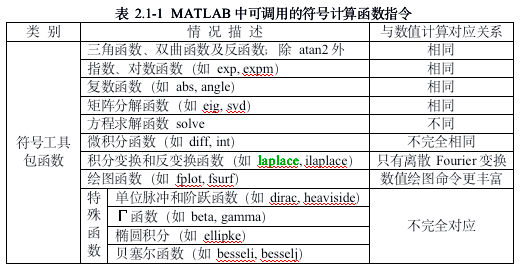

## 2.3.2  **符号关系和符号逻辑表述**

## **1、** **符号关系逻辑与数值关系逻辑的异同**

- 数值计算环境下的关系运算和逻辑运算，

            关系符和逻辑符两侧的是数值对象或数值表达式，结论是逻辑值

- 符号计算环境下的关系运算和逻辑运算，

            关系符和逻辑符两侧是符号对象：符号数字、符号变量、符号表达式

            符号关系式或逻辑式的处理取决于用户的目的：

            求解不等式：solve

            判断符号关系式或逻辑式是否成立：isAlways, logical

**2、** **纯关系、纯逻辑表述符及函数**

            处理数值对象和处理符号对象的关系和逻辑运算符符号形式和符号名称均相同，运算中是调用数值计算文件还是符号计算文件，完全由具体的处理对象属性（数值类还是符号类）决定

**3****、关系逻辑判断函数和直接逻辑判断函数**

La=isAlways(cond)    %对cond成立性或符号数是否非0给出逻辑判断

输入参数的数目不足。

出错 cond (line 24)
if issparse(A)

La=isAlways(cond, 'Unknown', 'false')    %同上，不显示任何警告提示
La=logical(cond)      %对cond成立性或符号数是否非0给出逻辑判断

**〖说明〗**

- **La=isAlways(cond****)****：**无法判断cond是否成立时，给出逻辑0判断

            同时，还会给出说明“无法判断”的警告信息

**            La=isAlways****(****cond,**** '****Unknown****'****,**** '****false****')****：**只给出逻辑0的判断

- logical指令主要用于各种纯符号数字的各种关系式及不含关系符的纯符号表达式和关系式的判断（表2.3-6）

【例2.3-1】

（1）数值关系运算

clear all					      	 %
A=10							         %

A = 10

B=sqrt(5);		                  %
Rn1=A>B		

Rn1 = logical
   1


W1=(A+B)^2;		               %(10+51/2)2;
W2=(A^2+2*A*B+B^2);          %
Rn2=abs(W1-W2)<abs(W1)*eps  %【W1-W2的绝对值小于运算误差】

Rn2 = logical
   1


（2）符号关系运算

a=sym(10);						   %
b=sqrt(sym(5));		         %
Rs1=a>b                     %建立不等式

$$Rs1 = \sqrt{5}<10$$

w1=(a+b)^2;		               %
w2=(a^2+2*a*b+b^2);
Rs2=w1-w2==0                %建立关系式

$$Rs2 = {\left(\sqrt{5}+10\right)}^{2}-20\,\sqrt{5}-105=0$$

（3）判断

isAlways(Rs1)

ans = logical
   1


isAlways(Rs2)

ans = logical
   1


logical (Rs1)                     %纯符号数字关系式

ans = logical
   1


logical (Rs2)                     %错判含关系符号对象纯数字表达式

ans = logical
   0


## 2.4 符号表达式和符号函数

2.4.1    **创建****符号表达式和符号方程**

**1.  ****符号表达式和符号方程概念**

**符号表达式**：为表达某种数学算式、实现某种计算目的，采用基本符号对象（数字、常数、变量）、运算符、函数命令等基本要素编写而成的M码。符号表达式中**不含等号、不等号这类的关系运算符**符号表达式可直接使用，也可借助“=”把其赋义于某符号变量或某符号函数

**符号方程：**由关系运算符连接两个符号表达式组合而成，表达某种约束关系。符号方程**一定包含等号、不等号这类的关系运算符**。

**2.  ****符号表达式和符号方程的创建**

- 先定义符号变量，然后再创建

- 任何包含符号对象的表达式或方程，将**继承**符号对象的属性。但要防止数值之间的双精度之类的**数值运算**

- 注意，工具包函数输入量或子括号中，不得有纯数字或纯数字表达式，

- 若有应用sym定义。

【例2.4-1】创建符号表达式和符号方程

clear all					      	         %
syms a x
Ex21=a*sin(1+sqrt(sym(5)))+1	         %

$$Ex21 = a\,\sin\left(\sqrt{5}+1\right)+1$$

Ex22=a*sin(1+sqrt(5))+sym(1)	         %错误

$$Ex22 = 1-\frac{6797541988628755\,a}{72057594037927936}$$

Eq21=x/(1+sin(pi/sym(2)+1))==0	         %

$$Eq21 = \frac{x}{\sin\left(\frac{\pi }{2}+1\right)+1}=0$$

Eq22=x/(1+sin(pi/sqrt(2)+sym(1)))==0	 %错误

$$Eq22 = \frac{x}{\sin\left(\frac{1813510324967609}{562949953421312}\right)+1}=0$$

whos Ex22 Eq22      %显示继承性

  Name      Size            Bytes  Class    Attributes

  Eq22      1x1                 8  sym                
  Ex22      1x1                 8  sym                



## 2.4.2   **创建符号函数**

1. **符号函数的概念**

**符号函数：**为表达变量间抽象或具体的约束关系而编写的M码。

- 符号函数由函数名、自变量名、函数体和赋值号组成

符号函数分为符号抽象函数和符号具体函数两类。

- **符号抽象函数**：只有函数名和自变量名，没有具体表达式描述的函数体

- **符号具体函数：**包含符号表达式或符号表达式数组描述的函数体

- 符号函数都是标量，不论函数体是标量还是数组

2. **符号抽象函数和符号具体函数的创建**

在符号函数中，构成函数关系的变量名必须明确指定。即在定义符号函

数时，不仅要指定函数名，而且要指定变量名。

**            syms f(x,y)**          `%`**创建抽象符号函数及其输入符号变量**

`            ====================================================`

**            syms x y a b**            `%`**创建基本符号变量**

**            f****(****x,y****)**** =exprs               **`%`**创建具体符号函数**

            =`===================================================`

**            f=symfun****(****exprs,[x,y]****)**** %****创建****符号函数****：****exprs****为函数体，****x****、****y****为自变量**

            =`==================================================`

**            formula(f)                        ****%****获符号函数的函数体****exprs**

**            argnames(f)                     ****%****获符号函数的自变量**

**〖说明〗**

- 函数体exprs可以是符号表达式或符号表达式数组，各种**变量**必须是已定义的符号变量

- f(x,y) =exprs创建符号数值函数时，exprs必须是符号数值常数，不能是双精度或其它数值类常数

 【例2.4-2】

（1）创建抽象符号函数

clear all					      	 %
syms f1(x,y)		
who


您的变量为:

f1  x   y   



（2）创建具体符号函数

syms a b;		%x、y已定义
F21(x,y)	=[a*sin(x);b*cos(y)]		

$$F21(x, y) = \left(\begin{array}{c} a\,\sin\left(x\right)\\ b\,\cos\left(y\right) \end{array}\right)$$

F22(x,y)	=symfun([1,a*x+b*exp(y)],[x,y])

$$F22(x, y) = \left(\begin{array}{cc} 1 & a\,x+b\,{\mathrm{e}}^{y} \end{array}\right)$$

（3）创建符号常数函数

G31(x,y)	=sym(1/2)

$$G31(x, y) = \frac{1}{2}$$

G32(x,y)	=symfun(sym(1/2),[x,y])

$$G32(x, y) = \frac{1}{2}$$

G33(x,y)	=1/2    %错，没有定义符号常数

错误使用 sym/subsindex (line 836)
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

（4）求已知函数的函数体和自变量

bf=formula(f1)

$$bf = f_{1}\left(x,y\right)$$

bF21=formula(F21)

$$bF21 = \left(\begin{array}{c} a\,\sin\left(x\right)\\ b\,\cos\left(y\right) \end{array}\right)$$

bG31=formula(G31)

$$bG31 = \frac{1}{2}$$


af=argnames(f1)

$$af = \left(\begin{array}{cc} x & y \end{array}\right)$$

aF21=argnames(F21)

$$aF21 = \left(\begin{array}{cc} x & y \end{array}\right)$$

aG31=argnames(G31)

$$aG31 = \left(\begin{array}{cc} x & y \end{array}\right)$$

## 3. **符号变量及自由符号变量的认定**

- 解题是围绕自由符号变量进行的，结果通常是用符号参数构成的表达式

- 自由符号变量可以人为指定，也可以自动认定（默认）。

- 自动认定的规则：

                *小写字母x是首选自由符号变量，其后的次序规则是：*

*                与x的ASCII码值之差的绝对值小的字母优先；*

*                绝对值相同时，ASCII码值大的字母优先。*

*                自动识别符号变量时，字母的优先次序为x,y,w,z,v等，*

*                但输出仍按字母表排序，大写字母优先*

- 自动识别表达式中自由符号变量的指令：

**                symvar****(expr)           ****列出表达式中的所有基本符号变量**

**                symvar****(expr, n)       ****列出表达式中****n****个符号自由变量**

**〖说明〗**

- expr可以是符号表达式、符号函数及由它们构成的符号表达式数组，如果是数组，该命令对自由符号的确认是对整个数组进行的

- 只能取正整数或inf，n=inf或n≥expr中变量名总数时，相当于省略n

【例2.4-3】

（1）各种符号对象的创建和自变量的认定

clear
syms b t u v w x y z X A			% 定义基本符号对象
C1=sym(2);C2= sym(pi);
xE1=exp(-1i*t)*sin(x*y)  		% 

$$xE1 = {\mathrm{e}}^{-t\,\mathrm{i}}\,\sin\left(x\,y\right)$$

E2=C1*x+5*X/u+C2*w*z+A	*xE1	   % 创建符号表达式

$$E2 = 2\,x+\frac{5\,X}{u}+A\,{\mathrm{e}}^{-t\,\mathrm{i}}\,\sin\left(x\,y\right)+\pi \,w\,z$$

f(y)=A*sin(x*y)*exp(-b*y)	   % 创建符号函数

$$f(y) = A\,{\mathrm{e}}^{-b\,y}\,\sin\left(x\,y\right)$$

Rf1=symvar(E2)					      %

$$Rf1 = \left(\begin{array}{cccccccc} A & X & t & u & w & x & y & z \end{array}\right)$$

Rf2=symvar(E2,3)					   % 

$$Rf2 = \left(\begin{array}{ccc} w & x & y \end{array}\right)$$

Rf3=symvar(f,2)					   %

$$Rf3 = \left(\begin{array}{cc} y & x \end{array}\right)$$

（2）符号数组中的变量和自由变量的认定

R1=A*sin(y)			          %

$$R1 = A\,\sin\left(y\right)$$

R2=abs(v*z)>1&z^2>=z		  %定义符号关系逻辑式

$$R2 = 1<\left|v\,z\right|\wedge z\leq z^{2}$$

Q=[E2,f(y);R1,R2]			  %定义符号数组的

$$Q = \left(\begin{array}{cc} 2\,x+\frac{5\,X}{u}+A\,{\mathrm{e}}^{-t\,\mathrm{i}}\,\sin\left(x\,y\right)+\pi \,w\,z & A\,{\mathrm{e}}^{-b\,y}\,\sin\left(x\,y\right)\\ A\,\sin\left(y\right) & 1<\left|v\,z\right|\wedge z\leq z^{2} \end{array}\right)$$

Rq2=symvar(Q)

$$Rq2 = \left(\begin{array}{cccccccccc} A & X & b & t & u & v & w & x & y & z \end{array}\right)$$

Rq2=symvar(Q,3)

$$Rq2 = \left(\begin{array}{ccc} w & x & y \end{array}\right)$$

（3）对自由变量的操作

dQ=diff(Q)      %【对默认变量求导】

$$dQ = \left(\begin{array}{cc} A\,y\,{\mathrm{e}}^{-t\,\mathrm{i}}\,\cos\left(x\,y\right)+2 & A\,y\,{\mathrm{e}}^{-b\,y}\,\cos\left(x\,y\right)\\ 0 & 0 \end{array}\right)$$

dQx=diff(Q,x)   %对指定变量x求导

$$dQx = \left(\begin{array}{cc} A\,y\,{\mathrm{e}}^{-t\,\mathrm{i}}\,\cos\left(x\,y\right)+2 & A\,y\,{\mathrm{e}}^{-b\,y}\,\cos\left(x\,y\right)\\ 0 & 0 \end{array}\right)$$

【例2.4-4】用符号法求方程$u w^{2}+z w=v$的解。

（1）产生符号表达式和符号函数

clear
syms u v w z				
Eq=u*w^2+z*w-v		 % 表达式

$$Eq = u\,w^{2}+z\,w-v$$

g(z)=u*w^2+z*w==v	 % 符号方程，“==”是关系运算符

$$g(z) = u\,w^{2}+z\,w=v$$

                    % g(z)不是以z为自由变量的函数

（2）symvar认定的自由变量

symvar(Eq,1)		    %		<5>

$$ans = w$$

symvar(g(z),1)	    %		<6> 

$$ans = w$$

（3）solve对默认自由变量解方程

R1=solve(Eq)		   % 关于w解方程u*w^2+z*w-v=0 <7>

$$R1 = \left(\begin{array}{c} -\frac{z-\sqrt{z^{2}+4\,u\,v}}{2\,u}\\ -\frac{z+\sqrt{z^{2}+4\,u\,v}}{2\,u} \end{array}\right)$$

R2=solve(g)		      % 关于w解g（z）所表达的方程 <8>  

$$R2 = \left(\begin{array}{c} -\frac{z-\sqrt{z^{2}+4\,u\,v}}{2\,u}\\ -\frac{z+\sqrt{z^{2}+4\,u\,v}}{2\,u} \end{array}\right)$$

（4）对变量z求解

S1=solve(Eq,z)	    %	eq的默认自由变量是w

$$S1 = \frac{v-u\,w^{2}}{w}$$

S2=solve(g(z),z)		 % g(z)的自由变量不是z，求解时需指定

$$S2 = \frac{v-u\,w^{2}}{w}$$

（5）检验求解结果的正确性

disp(simplify(subs(Eq,z,S1)))	%S1代替z，观察Eq是否为0

$$0$$

0  

ans = 0


disp(simplify(g(S2)))		  %S2代替z，观察g(S2)是否成立

$$\mathrm{TRUE}$$

% g(z)=u*w^2+z*w==v

【例2.1-5】数据对象及其识别指令的使用。

（1）生产三种不同类型的矩阵，给出不同的显示形式

clear
a=1;b=2;c=3;d=4;		% 产生4个数值变量
Mn=[a,b;c,d]			% 利用已赋值变量构成数值矩阵

Mn =      1     2
     3     4


Mc='[a,b;c,d]'		% 字符串中的a,b,c,d与前面输入的数值变量无关

Mc = '[a,b;c,d]'

Ms=sym(Mc)	                  % Ms是一个符号矩阵，它与前面各变量无关

$$Ms = \left(\begin{array}{cc} a & b\\ c & d \end{array}\right)$$

（2）三种矩阵的大小不同

SizeMn=size(Mn)    % 指令size(A):直接显示A的大小

SizeMn =      2     2


SizeMc=size(Mc)    % [r,c]=size(A)：矩阵的行数和列数分别返给r,c

SizeMc =      1     9


SizeMs=size(Ms)    %  m=size(A,n):返回矩阵A的行/列/页数,n=1/2/3

SizeMs =      2     2


（3）三种矩阵的类别不同

CMn=class(Mn)

CMn = 'double'

CMc=class(Mc)

CMc = 'char'

CMs=class(Ms)

CMs = 'sym'

（4）判断每种矩阵的类别

isa(Mn,'double')

ans = logical
   1


isa(Mc,'double')   % 是字符串

ans = logical
   0


isa(Ms,'sym') 

ans = logical
   1


（5）用whos观察内存变量的类别和其它属性

whos Mn Mc Ms        % whos(‘Mn’,’Mc’,’Ms’)

  Name      Size            Bytes  Class     Attributes

  Mc        1x9                18  char                
  Mn        2x2                32  double              
  Ms        2x2                 8  sym                 



# 2.5 符号表达式的简化重组和子对象置换

## 2.5.1   **符号表达式的简化**

**Nexpr=simpl****ify****(expr)**      预先设定的用模式对**expr**进行简化，可重复使用

**Nexpr=simplify(expr****,name,value****)**    在指定选项下对**expr**进行简化

〖说明〗

- **expr**是符号表达式、符号函数或由它们组成的数组。

                对数组操作是对数组的每个元素操作

- Name和value是选项字符串和选项值（表2.5-1），可多套使用。

                常用选取的参数如下：

                ‘IgnoreAnalyticConstraints’是简化规则，缺省值是false

                ‘Step’是简化轮数，缺省值是1

【例2.5-1】简化$f=\sqrt[3]{\frac{1}{x^{3}}+\frac{6}{x^{2}}+\frac{12}{x}+8}$。

syms x
f=(1/x^3+6/x^2+12/x+8)^(1/3)

$$f = {\left(\frac{12}{x}+\frac{6}{x^{2}}+\frac{1}{x^{3}}+8\right)}^{1/3}$$

g1=simplify(f)

$$g1 = {\left(\frac{{\left(2\,x+1\right)}^{3}}{x^{3}}\right)}^{1/3}$$

g2=simplify(f,'Steps',10,'IgnoreAnalyticConstraints', true)

$$g2 = \frac{1}{x}+2$$

2.5.2   **符号表达式的重写**

**Nexpr=rewrite(expr****,****'****target****'****)**    将expr等价地重写成target指定的形式

〖说明〗

- **expr**是符号表达式、符号函数或由它们组成的数组。

                对数组操作是对数组的每个元素操作

- target是希望得到的目标形式（表2.5-2）

【例2`.`5`-`2】

clear all
syms x
exp2sin =rewrite(exp(x),'sin')

$$f1 = b+a\,\sin\left(x\right)$$

exp2tan =rewrite(-(exp(x*2i)*1i-1i)/(exp(x*2i)+1),'tan')

$$s11 = b+c\,\sin\left(x\right)$$

syms a y t

$$s12 = b+a\,\log\left(y\right)$$

f=a*cos(y)
rf=rewrite(f,'exp')

$$s21 = b+d\,{\mathrm{e}}^{y}\,\cos\left(y\right)$$

## 2.5.3**符号表达式的子对象置换**

子对象的置换包括：变量置换，符号矩阵的元素置换，符号表达式中的标量用矩阵或数组置换 以及为使冗长符号表达式简化而实施的置换等。

**        rs=subs(s,old,new)         **用new置换s中所有的old后产生符号结果rs

**        rs=subs(s,new)           **用new置换s中所有出现的默认变量，然后计算s 

默认变量由symvar定义

**        [Nexpr,sigma]=****subexpr(****expr****)**      从**expr**中自动提取**冗子式**

                                                                并用sigma（默认）替代并重写expr

**        [Nexpr,var]=subexpr(expr,var)    **用var替代**冗子式**重写expr

**        rs=****subexpr(****expr, var****)**                   重写的expr 赋给rs

**        rs=****subexpr(****expr****)**

**        pretty****(****expr****)**                                    用编序#号替换expr中的冗子式，使表述简洁

〖说明〗

- s可以是**符号表达式、符号函数及由它们构成的符号数组**

                old可以是符号变量、符号表达式、符号数值及**元胞数组**；、

                new可以是数字、符号变量、符号矩阵以及符号数组和**元胞数组**，

                new是**数组**时用数组的每一元素代替old

- 不管new是符号类型还是双精度类型，也不管是置换部分变量还是置换全部变量

- expr是符号表达式、符号函数及由它们构成的符号数组。

                冗子式：重复次数较多或本身比较冗长的子表达式

【例2`.`5`-`3】

（1）单个符号变量或表达式的替换

clear all

$$s22 = b+d\,{\mathrm{e}}^{y}\,\cos\left(y\right)$$

syms a b c d x y t
f1=a*sin(x)+b						% 

$$f3(x) = d+\sin\left(c+x\right)=x$$

s11=subs(f1,a,c)					% 

$$s31(x) = \sin\left(x+\frac{\pi }{3}\right)+1=x$$

s12=subs(f1,sin(x),log(y))		%   

$$s32(x) = {\mathrm{e}}^{-x}+2=x$$

（2）多个符号变量或表达式的替换

s21=subs(f1,[a,sin(x)],[d*exp(y),cos(y)])	% 

$$f4(x, y) = x+y$$

s22=subs(f1,{a,sin(x)},{d*exp(y),cos(y)})	%   

$$s41(x, y) = a+b$$

（3）符号方程中子对象的替换

f3(x)=sin(x+c)+d==x							% 符号方程

$$s42(a, y) = y+\sin\left(a\right)$$

s31=subs(f3,[c,d],[sym(pi/3),1])				% 		<9>
s32=subs(f3,{sin(x+c),d},{exp(-x),2})		%		<10>  

$$f5 = \left(\begin{array}{cccc} a & b & \frac{c}{a} & d\\ d & c & b & a\,x \end{array}\right)$$

（4）符号函数中子对象的替换

f4(x,y)=x+y				      	% 符号函数及

$$s51 = \left(\begin{array}{cccc} \pi & b & \frac{c}{\pi } & d\\ d & c & b & \pi \,x \end{array}\right)$$

s41=subs(f4,[x,y],[a,b])	% 				<12>

$$s52 = \left(\begin{array}{cccc} \pi & b & \frac{c}{\pi } & d\\ d & c & b & \pi \,x \end{array}\right)$$

s42(a,y)=subs(f4,x,sin(a))	% 	<13> 

$$s53 = \left(\begin{array}{cccc} a & b & 7 & d\\ d & c & b & a\,x \end{array}\right)$$

（5）符号数组中子对象的替换

f5=[a,b,c/a,d;d,c,b,a*x]		   %符号数组

$$f5 = \left(\begin{array}{cccc} \pi & b & \frac{c}{a} & d\\ d & c & b & a\,x \end{array}\right)$$

s51=subs(f5,a,sym(pi))			% <15>置换f5中所有位置的a
s52=subs(f5,f5(1,1),sym(pi))  % 置换与f5(1,1)相同的所有元素

$$f6 = {\mathrm{e}}^{-b\,t}\,\cos\left(a\,t\right)$$

s53=subs(f5,f5(1,3),sym(7))   % <17>
f5(1,1)=sym(pi)				      % 只置换指定元素，不影响其它元素

（6）用符号数组替换表达式中的标量`, `结果是符号数组

f6=cos(a*t)*exp(-b*t)				% 创建符号表达式

ctt = 'double'

tt=0:0.01:2;							% 定义双精度数组

cs61 = 'sym'

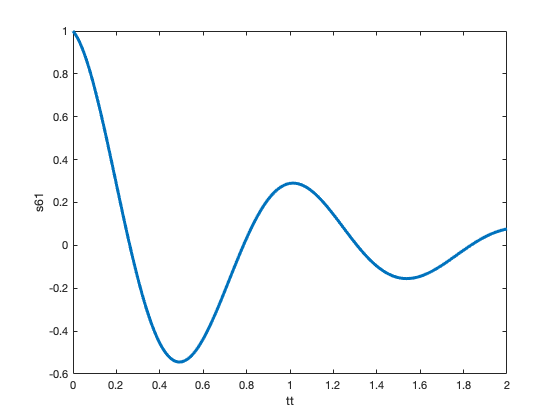

s61=subs(f6,{a,b,t},{6,1.2,tt});	% f6中符号变量被双精度数值置换		<21>
ctt=class(tt)

cs61=class(s61)						% 检验s61，可知仍是符号对象
plot(tt,s61,'LineWidth',3)	   %可接受双精度和符号数据绘图	<24>
xlabel('tt'),ylabel('s61') 		% 标注坐标轴名称

（7）两次置换得到符号数组

t1=0:0.01:2*pi;	                         %数值数组
k=[0.6;0.8;1];						       %（3*1）数值数组
f6=subs(subs(f1,{a,b},{k,2}),x,t1);  %符号数组<17>

ans = 'sym'

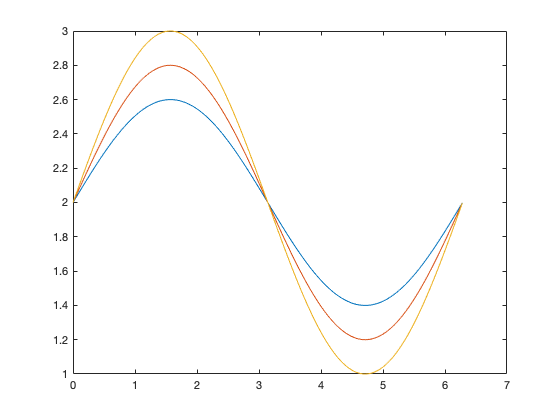

                                            %f1=a*sin(x)+b

class(f6)
plot(t1,f6) 	%

# 2.6 变精度计算及数字类型转换

## 2.6.1   **有限精度符号数和变精度计算**

- 相比数值计算，符号计算所需内存较大，计算速度较低为了兼顾计算精度和速度，可采用“变精度”算法同时可用有限精度的数值计算代替无法用封闭解析式表达的符号计算

                `digits`               **显示**当前环境下已设定的有限精度符号数的有效位数

                `digits(n)`          将指令后的有限精度符号数的有效位数设定为n

                `xn=vpa(x)`       据表达式x得到digits指定精度下的符号数字xn

                `xn=vpa(x,n)`    据表达式x得到n位有效数字的符号数字xn

                                        仅在运行本指令时起作用。

〖说明〗

- digits(n) 的精度控制只对之后的vpa(x)运算精度和显示位数有影响，对其它运算无影响。

- digits对vpa的影响直到下一个digits出现。vpa(x,n)只对本指令起作用。

- 位数来改变精度。当有效位数增加时，计算时间和占用的内存也增加。

- x可以是符号数、符号数表达式和符号数数组

- MATLAB会尽量将有限精度近似的影响控制在最小范围内。采用默认精度直接产生的近似数被isAlways判断为严格等于精准数

【例题】用三种运算方式表达式比较2/3的结果。

a1=2/3+pi   %数值型

a1 = 3.8083

a=sym(2/3),b=sym(pi)
a2=sym(a+b)   %符号运算
a3=vpa(a2)       %vpa型（默认32位）

**〖说明〗** 

- 三种运算方式中数值型运算的速度最快。 

            有理数型符号运算的计算时间和占用内存是最大的，但结果非常准确。 

- vpa型的任意精度符号运算比较灵活，可以设置任意有效精度，

            当保留的有效位数增加时，每次运算的时间和使用的内存也会增加。

## 2.6.2 **符号数字转换成****双精度数字**

MATLAB的某些指令，如integral等数值计算指令不接受符号类数字，只接受数值类数字，因此需进行数值类型转换。

**    Nd=double(Num_sym) **    **把符号数字****Num_sym****转换为双精度数字**

〖说明〗

- 符号数字有时与双精度数字在外观上相似，可用class判别数据类型。

- 一般情况下，Nd是符号数字`Num_sym`双精度近似。

- sym(HandNum)能把数字类数字转换成符号数字

- double('Num') 将字符串数字'Num'中的各个数字字符转换为字符的ASCII码数值组。

## 2.6.3 **不同类型数字的相互转换**

MATLAB中主要有三种形式相似的数字类型：

  **  双精度数字，符号数字，字符串数字**

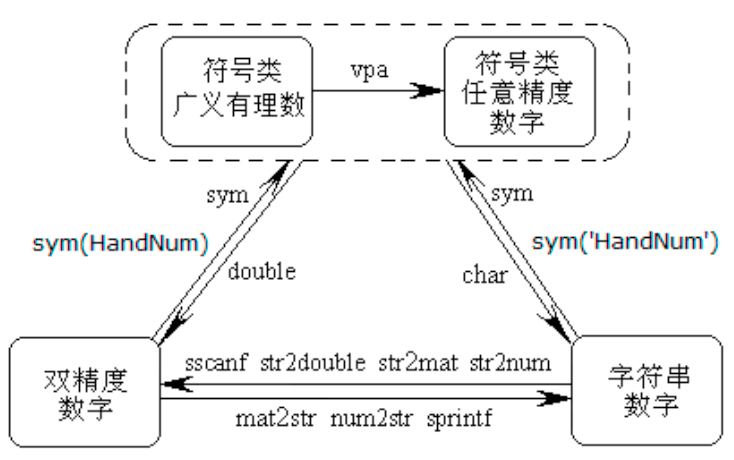

# 2.7 符号微积分

## 2.7.1   **序列****/****级数的符号求和**

**        F=symsum(f,k)                           **求f(k)的不定和

**        F=symsum(f,k,[a,b])                  **求确定和

**        F=symsum(f,k,a,b)**

**        B=symsum(A,dim,direction)    **在维度沿方向计算数组的累（计）和

〖说明〗

- f 是级数的通项表达式，可以是符号表达式、符号函数、符号数组、符号常数

- f是数组时，对每个元素逐个求和，但自变量定义在整个数组上。

- k取符号变量，缺省时，自变量由 symvar自动辨认；

- a、b可以是符号数值、符号表达式、符号函数、符号数组

- b可取有限整数或inf。a、b同时缺省，默认自变量区间为 [0, k-1]

- dim是求和维度，1表示列维度（默认），2表示行维度

                direction表示累计方向：forward（自上而下/自左而右）（默认）

                reverse（自下而上/自右而左）

【例2.7-1】 求   $\sum_{t=0}^{t-1}\left[t, k^{3}\right] \quad \sum_{k=1}^{\infty}\left[\frac{1}{(2 k-1)^{2}}, \frac{(-1)^{k}}{k}\right]$

syms k t;
f1=[t k^3];
f2=[1/(2*k-1)^2,(-1)^k/k];	

$$F2 = \frac{14912\,2^{1/4}}{4641}-\frac{6072064\,\sqrt{2}}{348075}+\frac{64\,2^{3/4}}{225}+\frac{1610027357}{6563700}$$

s1=symsum(f1)				 % 求不定和，f1的自变量被确认为t

$$VF2 = 224.92153573331143159790710032805$$

s2=symsum(f2,1,inf)  	 % 求确定和，f2的自变量被确认为k
                       % 自变量和取值区间是对整个数组而言的

## 2.7.2  **极限的符号计算**

极限是微积分最基础的概念，求极限是微积分解析的基本方法。

**        limit(f)                       **               **对默认变量求趋于****0****的极限**

**        limit(f,x,a)                       **         **求极限** 

**        limit(f,x,a,'right')           **         **求极限** 

**        limit(f,x,a,'left')                **       **求极限** 

〖说明〗

- f可以是符号表达式、符号函数及由它们构成的数组

- f为数组时，对元素逐个进行求极限，但自变量定义在整个矩阵上

##  2.7.3   **符号导数及级数展开**

大学本科高等数学中的大多数微积分问题，都能用符号计算解决

**        df=diff(f,n)             **                     **求**

**        df=diff(f,x1,****…****,xn)                      ****求 ****f****对****x1,x2,****…****,xn****的混合导数**

**        df=jacobian(f,v)            **             **多元向量函数的****jacobian****矩阵**

**        st=taylor(****f,var,a****)                        ****求****var=a****处的****5****阶泰勒级数**

**        r=taylor(f,var,a,Name,Valu****e****)   ****求给定选项下****f****的泰勒级数**

〖说明〗

- f可以是符号表达式、符号函数及由它们构成的数组

- f为数组时，求导和级数展开操作对元素逐个进行，但自变量定义在整个数组上。

- n缺省时默认n=1

- var缺省时，自变量由symvar自动确认；

                输入量a可以是（符号）数、符号变量、符号表达式，缺省默认a=0

- Name/Value取值见表2.7-1

【例2.7-a】两种重要极限$\lim _{t \rightarrow 0} \frac{\sin k t}{k t}$和$\lim _{x \rightarrow \infty}\left(1-\frac{1}{x}\right)^{k x}$

syms t x k
s=sin(k*t)/(k*t);        % sinc函数
f=(1-1/x)^(k*x);
Lsk=limit(s)				   % t趋于0
Ls1=limit(subs(s,k,1))		% 抽样函数sint/t的极限
Lf=limit(f,x,inf)			%

S1 = 包含以下字段的 struct :
    y: [1×1 sym]
    x: [1×1 sym]


Lf1=vpa(subs(Lf,k,sym('-1')),48)	%给出48位精度的自然数

【例2.7-b】 已知  $f=\left[\begin{array}{cc}{a} & {t^{3}} \\ {t \cos x} & {\ln x}\end{array}\right]$求$\frac{d f}{d x}, \quad \frac{d^{2} f}{d t^{2}}, \quad \frac{d^{2} f}{d t d x}$

syms a t x;

微分方程组的解 S1


f=[a,t^3;t*cos(x), log(x)];  % log(x)即求ln(x)

          x(t)                  y(t)


df=diff(f)					       % 默认变量x（整个数组）

$$\left(\begin{array}{cc} \frac{\cos\left(t\right)}{2}+C_{1}\,\sin\left(t\right) & C_{1}\,\cos\left(t\right)-\frac{\sin\left(t\right)}{2} \end{array}\right)$$

dfdt2=diff(f,t,2)			    % 自由变量t（整个数组）
dfdxdt=diff(diff(f,x),t)	    % 混合求导

2.7.4   **符号积分**

**F=int(f,var)                **求f对变量var的不定积分（不带积分常数）

**F =int(f,var,[a,b])      **求f对变量var在区间[a,b]的定积分

**F =int(f,var,[a,b],Name,Value)      **求指定设置下的**定积分**

〖说明〗

- f可以是符号表达式、符号函数及由它们构成的数组

- f为数组时，对每个元素逐个求积分，但自变量定义在整个数组上。

- var缺省时，自变量由 symvar(f,1)自动辨认

- a、b允许取任何数值、Inf、- Inf、符号表达式或符号函数

- Name/Value取值见表2.7-2

- 如果积分不可积，则给出错误提示并返回原函数

                函数太复杂也可能给不出积分，可用数值积分

【例2.3-c】 求 $\int \frac{1}{x} \sqrt{\frac{1+x}{x}} d x$。

clear	

$$X31 = \frac{\cos\left(t\right)}{2}+C_{1}\,\sin\left(t\right)$$

$$Y31 = C_{1}\,\cos\left(t\right)-\frac{\sin\left(t\right)}{2}$$

syms x

$$Y32 = 0.5\,\cos\left(t\right)+C_{4}\,\sin\left(t\right)$$

$$X32 = C_{4}\,\cos\left(t\right)-0.5\,\sin\left(t\right)$$

f=sqrt((1+x)/x)/x

$$Y33 = \frac{\cos\left(t\right)}{2}+C_{1}\,\sin\left(t\right)$$

$$X33 = C_{1}\,\cos\left(t\right)-\frac{\sin\left(t\right)}{2}$$

s=int(f,x)

【例2.3-d】求积分。

syms x positive

$$y = \frac{31\,x^{4}}{468}-\frac{x^{3}}{3}+\frac{125}{468}$$

syms y z
F2=int(int(int(x^2+y^2+z^2,z,sqrt(x*y),x^2*y),y,sqrt(x),x^2),x,1,2)
VF2=vpa(F2)				     %积分结果用32位符号数字表示

# 2.8 符号变换及应用

    Fourier变换，Laplace变换，Z变换，符号卷积

# 2.9 常微分方程的符号解法

## 2.9.1   **符号解法和数值解法的互补作用**

- 相比微分方程的数值解法，符号解法耗时多，可能得不到简单的解析解或封闭形式的解，甚至无法求解。

- 无论是初值问题还是边值问题，符号解法的指令形式相同且相当简单。

- 微分方程的符号解法和数值解法有很好的互补作用

 2.9.2   **常微分方程组****ODEs****概述**

        一般形式的微分方程组（ODEs）及附带条件

            F(yn(t),…,y’(t) ,y(t),t)=0

            yk-1(ak-1)=p,  k=1,2,…,k<n

## 2.9.3   **求微分方程的符号解算命令**

**        S=dsolve(eqs)                                   ** 求常微分方程（组）eqs的解

**        S=dsolve(eqs, cond)                          **求cond条件下eqs的解

**        S=dsolve(eqs, cond,Name,Value)   **  给定设置下求cond条件下eqs的解

**        [Y1,****…****,Yn]=dsolve(eqs, cond,Name,Value)   ** 

〖说明〗

- 输入量包括三部分：微分方程eq、初始条件或边界条件cond和指定的独立变量v。省略v，**默认**独立变量为小写字母**t**。

- 解一阶微分方程：①定义抽象函数，syms x(t)；②用x和diff(x,t)构建微分方程；③条件cond：x(0)；④求解。

- 解高阶微分方程：①定义抽象函数，syms x(t)；②定义各阶辅助导函数：

                Dx(t)=diff(x(t),t)，D2x(t)=diff(x(t),t,2)，D3x(t)=diff(x(t),t,3)	

                    ① 用x，Dx，D2x，D3x构建微分方程；④条件cond：x(0) = = a，

                    Dx(0) = = b；D2x(0) = = c；⑤求解。

             写微分方程时最好遵循“**导数在前函数在后，导数降阶排序**”的次序，否则可能出错。

- Name/Value取值见表2.9-1

- 输出量S是符号数组或**构架数组**：单因变量微分方程组的解是符号数组

                n个因变量微分方程组的解是构架S.name，域名是求解的因变量名，应变量的解存放在域中

- 既找不到显式解又找不到隐式解，则发布警告信息并置S为空符号对象

## 2.9.4 **  微分方程符号解示例**

【例2.9-1】求$\frac{d x}{d t}=y, \quad \frac{d y}{d t}=-x$  的解

**（1）一阶方程组求解步骤**

clear all					     % <1>

$$yn = \left(\begin{array}{cccccccc} \frac{2}{3} & \frac{125}{468} & 0 & -\frac{209}{156} & -\frac{394}{117} & -\frac{641}{156} & 0 & \frac{6605}{468} \end{array}\right)$$

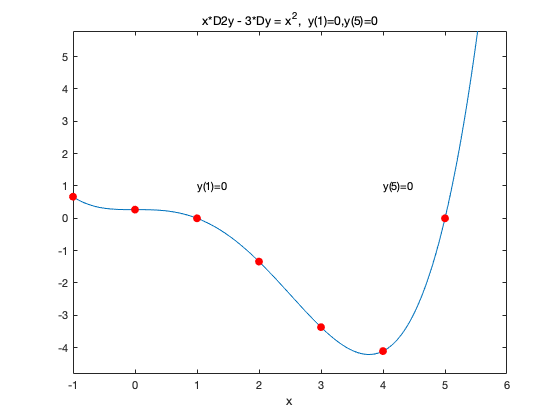

syms x(t) y(t)			   	% 	<2>
eq11=diff(x,t)-y;		   	% 	<3>
eq12=diff(y,t)==-x;		      % 			<4>
cond=x(0)==sym(0.5);	     %只设了一个初始条件，
S1=dsolve(eq11,eq12,cond)	%解只有一个常数	C1			
disp('  ')
disp('微分方程组的解 S1')
disp([blanks(10),'x(t)',blanks(18),'y(t)'])

disp([S1.x,S1.y])  

**（2）尽量少用多输出量数组，**

[X31,Y31]=dsolve(eq11,eq12,cond)	      % <12>  
[Y32,X32]=dsolve(eq11,eq12,'x(0)=0.5')	 % 输出排序出错

S = 包含以下字段的 struct :
    y: [2×1 sym]
    z: [2×1 sym]


[Y33,X33]=dsolve(eq11,eq12,cond)	       % 输出排序出错

S.y


$$\left(\begin{array}{c} \frac{v+2\,u\,w-\sqrt{v^{2}+4\,u\,w\,v-4\,u\,w}}{2\,u}-w\\ \frac{v+2\,u\,w+\sqrt{v^{2}+4\,u\,w\,v-4\,u\,w}}{2\,u}-w \end{array}\right)$$

S.z


$$\left(\begin{array}{c} -\frac{v+2\,u\,w-\sqrt{v^{2}+4\,u\,w\,v-4\,u\,w}}{2\,u}\\ -\frac{v+2\,u\,w+\sqrt{v^{2}+4\,u\,w\,v-4\,u\,w}}{2\,u} \end{array}\right)$$

【例2.9-2】求解两点边值问题：$x y^{\prime \prime}-3 y^{\prime}=x^{2}, y(1)=0, y^{\prime}(1)=-0.75$

（1）求边值问题

y=dsolve('x*D2y-3*Dy=x^2','y(1)=0,y(5)=0','x') 

（2）观察解的图形

xn=-1:6;
yn=subs(y,'x',xn)		

$$s = 0.69829942170241042826920133106081$$

ezplot(y,[-1,6])	%符号计算绘图

$$xs = 2.0$$

hold on
plot([1,5],[0,0],'.r','MarkerSize',20)
text(1,1,'y(1)=0')
text(4,1,'y(5)=0')
title(['x*D2y - 3*Dy = x^2',',  y(1)=0,y(5)=0'])
plot(xn,yn,'.r','markersize',20)    %数值计算绘图
hold off 

# 2.10 符号矩阵分析和代数方程解	

## 2.10.1 **符号矩阵分析**

- 符号矩阵和数值矩阵运算指令基本形式相同。

- 常用矩阵分析和解算指令见表2.10-1

                colspace(A)                    矩阵的列空间基

                det(A)                             矩阵行列式｜A｜

                [V,D]=eig(A)                 特征值分解，AV=VD

                inv(A)                             逆矩阵A-1

                rank(A)	矩阵秩

                poly(A)                           矩阵的特征多项式

                s=svd(A)                         符号矩阵的奇异值

                [U,S,V] =svd(vpa(A))    符号矩阵的奇异值分解

                expm(A)                         方阵A的指数函数阵eA

                [V,J]=jordan(A)             矩阵A的jordan分解，使AV=VJ

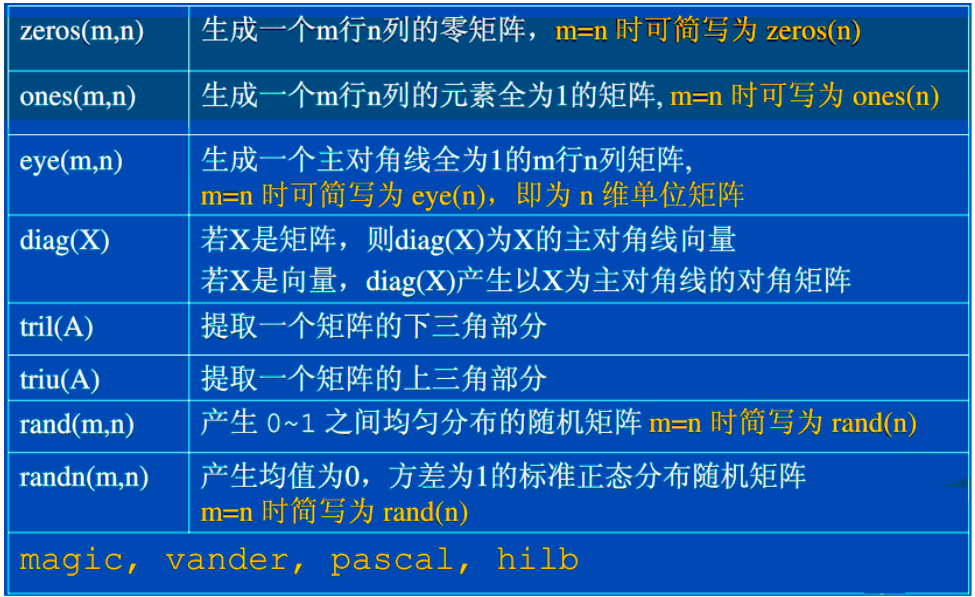

【例2.6-1】

（1）

syms a11 a12 a21 a22
A=[a11,a12;a21,a22]
DA=det(A)
IA=inv(A)

（2）

EA=subexpr(eig(A),'D')  

2.10.2 **线性方程组的符号解**

求解线性方程组AX=B方法：

- 用矩阵除求解： X=A\B

- 用命令求解：[X,r]=linsolve(A,B)

【例 2.6-3】求解线性方程组

$\begin{array}{l}{d+\frac{n}{2}+\frac{p}{2}=q} \\ {n+d+q-p=10} \\ {q+d-\frac{n}{4}=p} \\ {q+p-n-8 d=1}\end{array}$ →  $\left[\begin{array}{cccc}{1} & {\frac{1}{2}} & {\frac{1}{2}} & {-1} \\ {1} & {1} & {-1} & {1} \\ {1} & {-\frac{1}{4}} & {-1} & {1} \\ {-8} & {-1} & {1} & {1}\end{array}\right]\left[\begin{array}{l}{d} \\ {n} \\ {p} \\ {q}\end{array}\right]=\left[\begin{array}{c}{0} \\ {10} \\ {0} \\ {1}\end{array}\right]$

（1）采用‘矩阵除’的线性方程解法

A=sym([1 1/2 1/2 -1;1 1 -1 1;1 -1/4 -1 1;-8 -1 1 1]);
b=sym([0;10;0;1]);    % 创建符号数组

sh =   ParameterizedFunctionSurface - 属性:

    XFunction: [1×1 sym]
    YFunction: [1×1 sym]
    ZFunction: [1×1 symfun]
       URange: [0 1.5708]
       VRange: [0 4.7124]
    EdgeColor: [0 0 0]
    LineStyle: '-'
    FaceColor: 'interp'

  显示 所有属性


X1=A\b

（2）采用solve 指令的一般代数方程解法

syms d n p q
eq1=d+n/2+p/2-q;		   %	 <4>
eq2=d+n-p+q-10;		   %
eq3=d-n/4-p+q;			%
eq4=-8*d-n+p+q-1;		%
S=solve([eq1,eq2,eq3,eq4],[d,n,p,q]);	% 输入量为数组
disp(['  d','  n','  p','  q'])

sh1 =   ParameterizedFunctionSurface - 属性:

    XFunction: [1×1 sym]
    YFunction: [1×1 sym]
    ZFunction: [1×1 symfun]
    EdgeColor: [0 0 0]
    LineStyle: '-'
    FaceColor: 'interp'

  显示 所有属性


disp([S.d,S.n,S.p,S.q])						%	  <10>  

# 2.10.3 **各类等式****/****不等式方程的符号解**

线性方程、非线性方程和超越方程等一般方程的求解指令：

**        S=solve(eqn, var)                          **按默认方式求单个方程的解

**        S=solve(eqns, vars)                    **eqns/vars输入量之间用（，）隔开

**        S=solve(eqn, var,Name,Value)   **  按给定方式求方程的解

**        S=vpasolve(eqn, var,init_guess, 'random',RV)   **求有限精度的符号解

〖说明〗 

- eqn是符号方程（等式或不等式）、符号表达式或由它们构成的**数组**

- 输入量var可以是符号标量，也可以是多个符号变量构成的符号数组

                var缺省时，被求解的n个变量由symvar(eqln,n)自动确认；

- 输出量S是符号数组或**构架数组**：一元方程组的解是符号数组

            n元方程组的解是构架S.name，域名是求解的变量名，

            变量的解存放在域中，显示求解结果的援引方式：S.v1,S.v2,…,S.vn

- Name/Value取值见表2.10-2

- 得不到封闭型解析解时，如果不存在其它不确定参数，则给出数值解。

    【例2.6-4】求解方程组 $\begin{array}{l}{u y^{2}+v z+w=0} \\ {y+z+w=0}\end{array}$   关于y、z的解

syms u v w x y z
S=solve(u*y^2+v*z+w==0,y+z+w==0,y,z)		% <1>
disp('S.y'),disp(S.y),disp('S.z'),disp(S.z)	%	  <2> 

【例2.6-6】求解$(x+2)^{x}=2$

clear all;
syms x;
s=solve('(x+2)^x=2',x)       % 无解析解时给出数值解。
xs=(s+2)^s						      % 验算		<3> 

# 2.11  符号函数的可视化

符号计算结果的可视化方法：

-  利用计算获得的符号表达式直接绘图

- 根据获得的符号表达式或符号数值结果，转换成数值数据，再利用数值绘图指令绘图

## 2.11.1 **功能绘图命令汇集**

MATLAB2016a版开始启用了新的绘图命令（表2.11-1），可接受符号表达式、

符号函数、符号隐函数及匿名或具名函数句柄和M文件函数

## 2.11.2 **线图绘制及修饰**

fplot(f)                                  绘制平面曲线的简单格式

fp=fplot(f,[xmin,xmax],LineSpec,Name,Value)      

fplot(xt,yt)                            绘制x=x(t)和y=y(t)描写的平面曲线简单格式

fp=fplot(xt,yt,LineSpec,Name,Value)         

plot3(xt.yt,zt)                        绘制x(t),y(t),z(t)描写的三维空间曲线

fp=fplot3(xt.yt,zt,[tmin,tmax] ,LineSpec,Name,Value)                  

〖说明〗

- 输入函数可以是符号表达式、符号函数、符号参变量表达或函数句柄

                f， xt，yt, zt；分别表达的含义是y=f(x)， x=x(t)，y=y(t),  z=z(t)

                这些输入量只有一个独立变量。

- 自变量[xmin,xmax] 和[tmin,tmax]缺省时均为[5,-5]

- 函数画图指令与数值画图指令已相互融合，

                  LineSpec指定曲线的颜色、线型、样点形状等，表5.2-2, 表5.2-3, 表5.2-4

                  Name/Value曲线的粗细、标识点大小等，见表5.2-5

- 输出量fp保存所绘图形对象全部结构要素。

                可对轴系要素（如线粗、坐标等）进行观察和修改（见第5章）

                如果希望通过编码对图形修改，就应生成输出量fp

【例2.11-1】 绘制函数$e^{-x} \sin x$的图形

（1）符号表达式

clear,figure

sh =   ParameterizedFunctionSurface - 属性:

    XFunction: [1×1 sym]
    YFunction: [1×1 sym]
    ZFunction: [1×1 symfun]
       URange: [0 1.5708]
       VRange: [0 4.7124]
    EdgeColor: [1 0 1]
    LineStyle: '-'
    FaceColor: 'interp'

  显示 所有属性


syms x

sh1 =   ParameterizedFunctionSurface - 属性:

    XFunction: [1×1 sym]
    YFunction: [1×1 sym]
    ZFunction: [1×1 symfun]
    EdgeColor: 'none'
    LineStyle: '-'
    FaceColor: 'interp'

  显示 所有属性


f1=exp(-x)*sin(x);					    %				<3>
Lh1=fplot(f1,'r:','LineWidth',8)	  %		<4>

（2）符号函数

f2(x)=exp(-x)*sin(x);			% 					<5>
hold on							% 			<6>
fplot(f2,'b-','LineWidth',4)	% 		<7>

（3）参变量表达式

syms t
u=t;v=exp(-t)*sin(t);			% 				<9>

sh =   ParameterizedFunctionSurface - 属性:

    XFunction: [1×1 sym]
    YFunction: [1×1 sym]
    ZFunction: [1×1 symfun]
       URange: [0 1.5708]
       VRange: [0 4.7124]
    EdgeColor: [0 0 0]
    LineStyle: '-'
    FaceColor: 'interp'

  显示 所有属性


fplot(u,v,'y-','LineWidth',1)	% 		<10>
hold off							% 						<11>

（14）图形修改

legend('符号表达式 f1','符号函数 f2(x)','参数表达式  u，v')% <12>
title('输入f 可用三种不同形式编码')		% 					<13>
xlabel('x'),ylabel('y')					%					<14>

## 2.11.3 **面图绘制及修饰**

**fsurf(fxy)                            ****绘制空间曲面的简单调用格式**

**fs=fsurf(fxy,** **[xmin,xmax,ymin,ymax],LineSpec,Name,Value)      **

**fsurf(Xuv,Yuv,Zuv)          ****绘制参数方程表示的空间曲面的简单调用格式**

**fs= fsurf(Xuv,Yuv,Zuv,[umin,umax,vmin,vmax],LineSpec,Name,Value)   **

〖说明〗

n 输入量**fxy****，****Xuv****，****Yuv****，****Zuv**可以是符号函数、符号表达式、函数句柄、  

分别表达的含义是**z=f(x,y)****，****Xuv =x(s,t)****，****Yuv =y(s,t)****，****Zuv =z(s,t)**

这些输入量有两个独立变量

n 输入量[xmin,xmax, ymin,ymax]和[umin,umax,vmin,vmax]默认值均为[5,-5]

n 函数画图指令与数值画图指令已相互融合，

      LineSpec指定曲线的颜色、线型、样点形状等，表5.2-2, 表5.2-3, 表5.2-4

      Name/Value曲线的粗细、标识点大小等，见表5.2-5

n 输出量fs保存所绘图形对象全部结构要素。

可对轴系要素（如线粗、坐标等）进行观察和修改（见第5章）

如果希望通过编码对图形修改，就应生成输出量fs

其它三维绘图指令使用方法与fsurf类似。

【例2.11-2】

clear 
syms s t

sh1 =   ParameterizedFunctionSurface - 属性:

    XFunction: [1×1 sym]
    YFunction: [1×1 sym]
    ZFunction: [1×1 symfun]
    EdgeColor: [0 0 0]
    LineStyle: '-'
    FaceColor: 'interp'

  显示 所有属性


x=cos(s)*cos(t);				%
y=cos(s)*sin(t);				%
z(s,t)=sin(s);						%

subplot(1,2,1)
sh=fsurf(x,y,z,[0,pi/2,0,3*pi/2]) 	%矩形域
shading interp
colormap(spring)					%
light('position',[0,0,-10],'style','local')		%   
light('position',[-1,-0.5,2],'style','local')

sh =   ParameterizedFunctionSurface - 属性:

    XFunction: [1×1 sym]
    YFunction: [1×1 sym]
    ZFunction: [1×1 symfun]
       URange: [0 1.5708]
       VRange: [0 4.7124]
    EdgeColor: [1 0 1]
    LineStyle: '-'
    FaceColor: 'interp'

  显示 所有属性


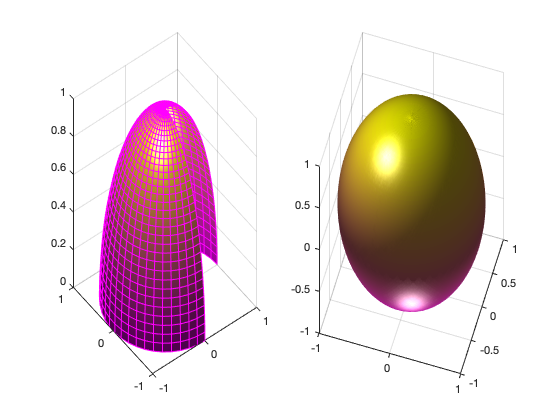

sh1 =   ParameterizedFunctionSurface - 属性:

    XFunction: [1×1 sym]
    YFunction: [1×1 sym]
    ZFunction: [1×1 symfun]
    EdgeColor: 'none'
    LineStyle: '-'
    FaceColor: 'interp'

  显示 所有属性


material([0.5,0.5,0.5,10,0.3])		

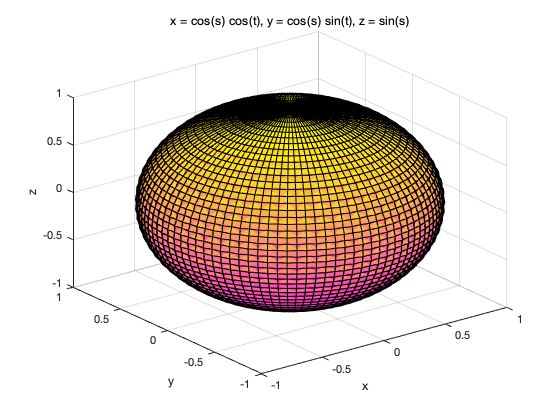


subplot(1,2,2)
sh1=fsurf(x,y,z,[0,pi/2,0,3*pi/2,'circ']) %圆形域

view(17,40)						%
shading interp
colormap(spring)					%
light('position',[0,0,-10],'style','local')		%   
light('position',[-1,-0.5,2],'style','local')
material([0.5,0.5,0.5,10,0.3])			
	 



f(x)=


sh.EdgeColor='1,0,1'    %使得经纬线消失，也可改变其颜色

         2
1 - ----------
    exp(x) + 1



sh1.EdgeColor='none'

clear 

$$fxint = 2\,\log\left({\mathrm{e}}^{x}+1\right)-\log\left(4\right)-x$$

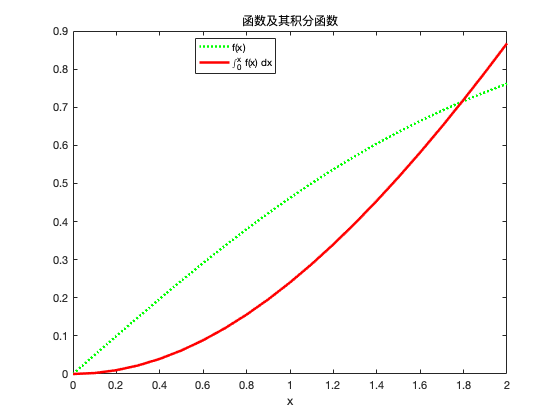

syms s t
x=cos(s)*cos(t);				%
y=cos(s)*sin(t);				%
z(s,t)=sin(s);						%

subplot(1,2,1)
sh=fsurf(x,y,z,[0,pi/2,0,3*pi/2]) 	%矩形域
shading interp

colormap(spring)					%
light('position',[0,0,-10],'style','local')		%   
light('position',[-1,-0.5,2],'style','local')

$$gy = \log\left(-\frac{1}{\frac{y}{2}-\frac{1}{2}}-1\right)$$

material([0.5,0.5,0.5,10,0.3])		

$$gyint = 2\,\log\left(y+1\right)+\log\left(-\frac{1}{\frac{y}{2}-\frac{1}{2}}-1\right)\,\left(y-1\right)$$


subplot(1,2,2)
sh1=fsurf(x,y,z,[0,pi/2,0,3*pi/2,'circ']) %圆形域
view(17,40)						%
shading interp
colormap(spring)					%
light('position',[0,0,-10],'style','local')		%   
light('position',[-1,-0.5,2],'style','local')
material([0.5,0.5,0.5,10,0.3])			
	 


sh.EdgeColor='1,0,1'    %使得经纬线消失，也可改变其颜色
sh1.EdgeColor='none'

clf

$$TL1 = \frac{x^{6}\,y^{2}}{12}-\frac{x^{6}}{6}+\frac{x^{4}\,y^{3}}{12}-\frac{x^{4}\,y}{2}-\frac{x^{2}\,y^{6}}{720}+\frac{x^{2}\,y^{4}}{24}-\frac{x^{2}\,y^{2}}{2}+x^{2}-\frac{y^{7}}{5040}+\frac{y^{5}}{120}-\frac{y^{3}}{6}+y$$

ezsurf(x,y,z,[0,pi/2,0,3*pi/2,'circ'])

## 2.11.4 **符号数学和可视化应用**

先将符号计算结果数值化，再用数值绘图指令实现可视化。

【例2.8-3】求函数$y=f(x)=1-\frac{2}{1+e^{x}}$的积分，用plot指令绘制函数及其积分函数的曲线。对反函数积分的两种算法进行可视化比较。

（1）求函数积分

clear

$$Fxy = \sin\left(x^{2}+y\right)$$

syms x y real				%

$$Fxy\_TL1 = \sin\left(x^{2}+y\right)-y+\frac{x^{2}\,y^{2}}{2}-\frac{x^{2}\,y^{4}}{24}-\frac{x^{4}\,y^{3}}{12}+\frac{x^{2}\,y^{6}}{720}-\frac{x^{6}\,y^{2}}{12}+\frac{x^{4}\,y}{2}-x^{2}+\frac{x^{6}}{6}+\frac{y^{3}}{6}-\frac{y^{5}}{120}+\frac{y^{7}}{5040}$$

fx=1-2/(1+exp(x));			%
disp('f(x)=')
pretty(fx)
disp('  ')
fxint=int(fx,x,0,x)		% 

（2）用数值绘图指令plot画图

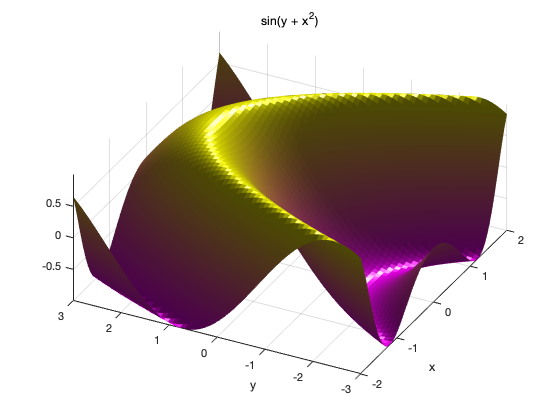

错误使用 light
Light 类中没有 e 属性。

xk=0:0.1:2;					%
fxk=subs(fx,x,xk);			%

fxintk=subs(fxint,x,xk);	%
plot(xk,fxk,'g:',xk,fxintk,'r','LineWidth',2.5)%
title('函数及其积分函数')
xlabel('x')
legend('f(x)','\int^x_0 f(x) dx','Location','best')  

（3）求反函数及返积分

gy=simplify(subs(finverse(fx),x,y)) 	% 求反函数
gyint=simplify(int(gy,y,0,y))			%  

（4）验证函数与反函数的互反性

gf=simplify(subs(gy,y,fx))			%  

（5）验证函数积分与反函数积分关于“自变量与函数值所围条形面积”的互补性

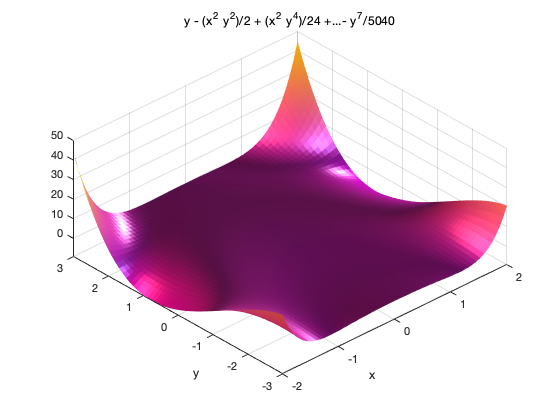

yk=subs(fx,x,xk);			% 
gyintk=subs(gyint,y,yk);	%  

GYintk=xk.*fxk-fxintk;		%
plot(yk,gyintk,'r')
hold on
plot(yk,GYintk,'+k')
hold off
xlabel('y')
legend('直接法计算反函数积分', '互补法求反函数积分','location','best')  

## 2.11.5 可视化与数据探索

【例2.8-4】

（1）

TL1=evalin(symengine,'mtaylor(sin(x^2+y),[x,y],8)')% 

(2)

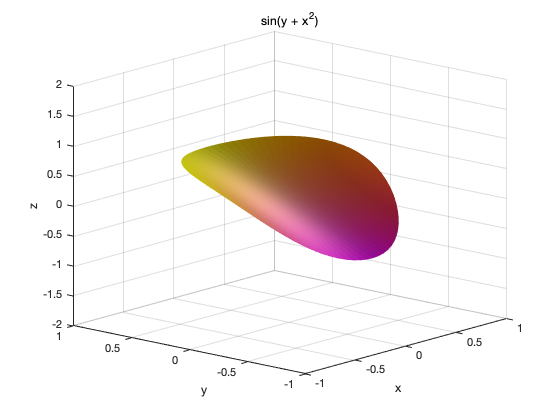

Fxy=sym('sin(x^2+y)')

Fxy_TL1=Fxy-TL1			% 

（3）

figure(1)							%
ezsurf(Fxy,[-2,2,-3,3])			%
shading interp					%
view([-63,52])					%
colormap(spring)
light,light('position',[-10,4,50],'e','local','color','r')  

（4）

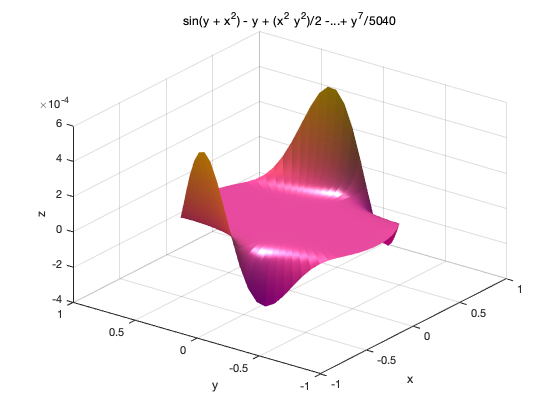

figure(2)

ezsurf(TL1,[-2,2,-3,3])
shading interp
view([-43,54])
colormap(spring) 
light
light('position',[-10,2,2],'style','local','color',[0.8,0.3,0.3]) 
light('position',[-2,-10,2],'style','local','color',[0.4,0.5,0.7]) 

（5）

figure(3)
ezsurf(Fxy,[-0.5,0.5,-0.5,0.5],'circ')      %
axis([-1,1,-1,1,-2,2])
shading interp
colormap(spring) 
view([-49,17])
light
light('position',[-30,0,-2],'style','local','color','r')  

（6）

figure(4)
ezsurf(Fxy_TL1,[-0.5,0.5],'circ')
shading interp
colormap(spring) 
view([-53,34])
light
light('position',[-10,15,0],'style','local','color',[0.8,0.3,0.3]) 